# **demo of Im2mesh package**

**With the **`'preserve'`** option during 2d mesh generation**

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size (optional).

x = 250; y = 250; width = 300; height = 300;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function bounds2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Polyshape

Polyshape is a MATLAB built-in object for polygon-like shapes. We can use object functions of polyshape to create single-part or multi-part geometry. Please refer to the following webpage about object functions of polyshape.

[https://www.mathworks.com/help/matlab/ref/polyshape.html](https://www.mathworks.com/help/matlab/ref/polyshape.html)

## Single-part geometry

### A polyshape

Let's create a polyshape (for a single-part geometry). 

Suppose we want a square with a hole.

% square
vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);

Scale the unit square with respect to its centroid to create a tiny square, and rotate.

% scale
[x,y] = centroid(psSq);
refpoint = [x,y];
scale_factor = 0.15;
psSqTiny = scale(psSq, scale_factor, refpoint);

% rotate
[x,y] = centroid(psSqTiny);
refpoint = [x,y];
psSqTiny = rotate(psSqTiny, 45, refpoint);

Perform boolean operation to create a square with a hole.

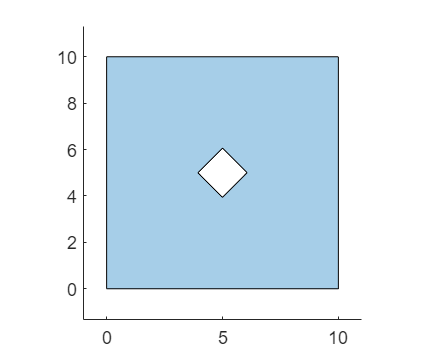

psSqHole = subtract(psSq, psSqTiny);

plot(psSqHole); 
axis equal

### Polygonal boundary

We use function polyshape2bound to convert a cell array of polyshape to a cell array of polygonal boundary. 

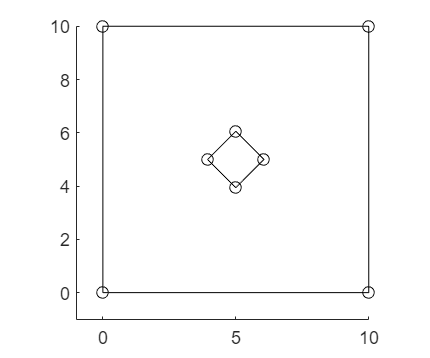

psCell = {psSqHole}; % psCell is a cell array of polyshape

bounds = polyshape2bound(psCell);

% plot boundaries and show all vertices
plotBounds(bounds,false,'ko-')

### Generate mesh via MESH2D

To generate mesh, we use function bounds2mesh.

Note that function bounds2mesh uses [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda) as mesh generator.

hmax = 500; 
grad_limit = 0.25;
opt = [];
opt.tf_preserve = 1;

[vert,tria,~,vert2,tria2] = bounds2mesh( bounds, hmax, grad_limit, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          2                 12                  8
          5                 20                 28


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          0                  8                  8
          1                  8                  8


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------



Plot mesh.

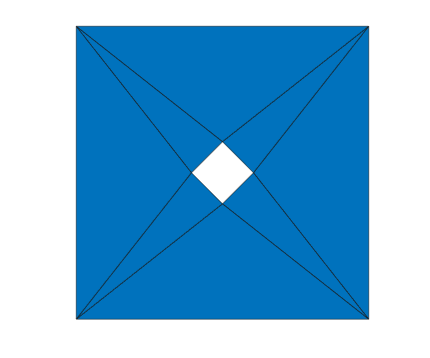

color = 1;
plotMeshes(vert,tria, [], color);

### Add mesh seeds to boundary

See demo16 for more examples. [https://mjx888.github.io/im2mesh_demo_html/demo16.html](https://mjx888.github.io/im2mesh_demo_html/demo16.html)

We use function xyRange to get the range of x y coordinates in boundary or polyshape.

[xmin, xmax, ymin, ymax] = xyRange( bounds );

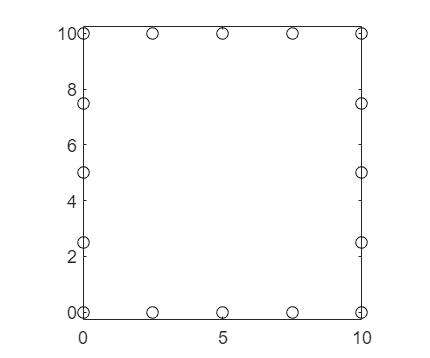

points = [xmin, ymin;
          xmin, ymax;
          xmax, ymax;
          xmax, ymin;
          xmin, ymin;
          ];

iters = 2;
points = insertMidPnt( points, iters );

plot( points(:,1), points(:,2), 'ko' ); 
axis equal

We use function addPnt2Bound to add point to boundary. 

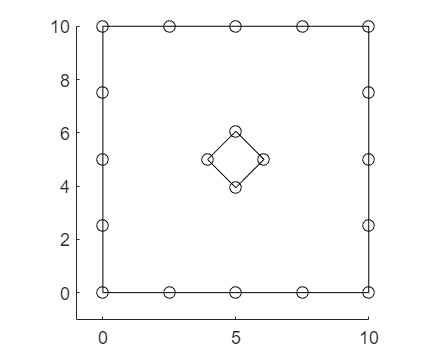

tol_dist = 1e-2;    % distance tolerance
newB = bounds;
newB = addPnt2Bound( points, newB, tol_dist );

% show all vertices
plotBounds( newB, false, 'ko-' );  

### Generate mesh via MESH2D

To generate mesh, we use function bounds2mesh.

Note that function bounds2mesh uses [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda) as mesh generator.

hmax = 500; 
grad_limit = 0.25;
opt = [];
opt.tf_preserve = 1;
opt.tf_smooth = 1;

[vert,tria,tnum,vert2,tria2] = bounds2mesh( newB, hmax, grad_limit, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          1                 20                 20
          3                 20                 28


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          0                 20                 20
          5                 20                 54


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------



Plot mesh.

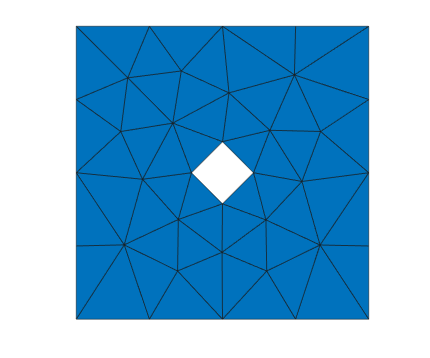

color = 1;
plotMeshes(vert,tria,tnum, color);

We can use function tricost to check the mesh quality. 

% tricost( vert, tria );

## Multi-part geometry

### Multiple polyshapes

Let's create multiple polyshapes for multi-part geometry.

clearvars

Start with a square.

vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);

Create a circle.

t = 0.05:0.25:2*pi;
x1 = 5 + 2*cos(t);
y1 = 5 + 2*sin(t);
psCircle = polyshape(x1,y1);

Plot them together.

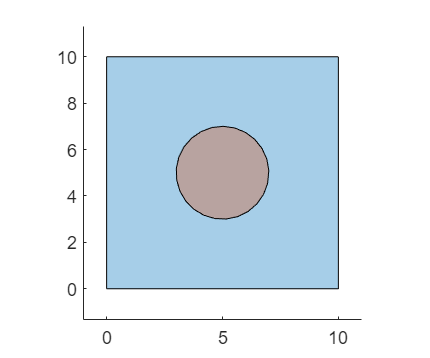

plot( [psSq; psCircle] ); 
axis equal

We saw that they are overlapped.

### Boolean operations

We use boolean operations to remove overlapped regions.

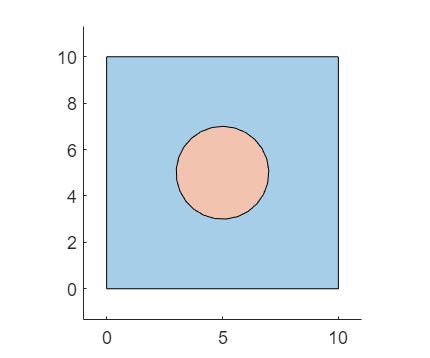

psBlock = subtract( psSq, psCircle );

plot( [psBlock; psCircle] ); 
axis equal

### Cell array of polyshape

We put them into a cell array - psCell. Each element in psCell represent different parts. It's like labelling.

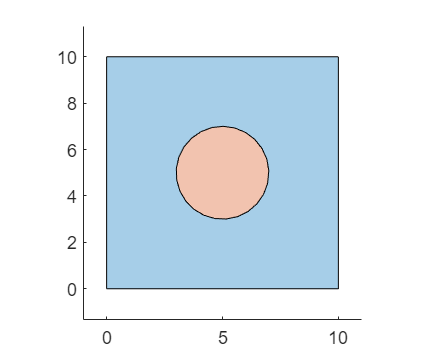

psCell = { psBlock; psCircle };

% plot psCell
figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

Convert the cell array of polyshape 'psCell' to a cell array of polygonal boundaries 'bounds'

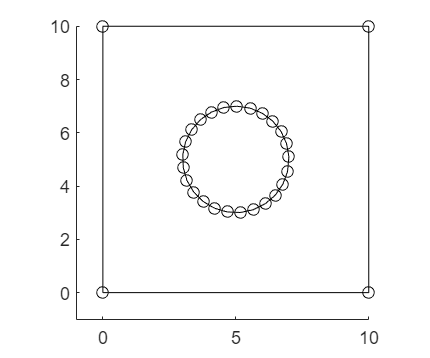

bounds = polyshape2bound(psCell);

% plot boundaries and show all vertices
plotBounds(bounds,false,'ko-')

### Add intersect points (this is optional)

Polyshape objects are not able to find intersect points automatically. Therefore, we use function addIntersectPnts to add intersect points to 'bounds'. 

Note that if we don't add intersect points, mesh generation **may** fail.

tol_intersect = 1e-6;   % distance tolerance for intersect
bounds = addIntersectPnts( bounds, tol_intersect );

### Generate mesh via MESH2D

To generate mesh, we use function bounds2mesh.

Note that function bounds2mesh uses [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda) as mesh generator.

hmax = 500; 
grad_limit = 0.25;
opt = [];
opt.tf_preserve = 1;
opt.tf_smooth = 0;

[vert,tria,tnum,vert2,tria2] = bounds2mesh( bounds, hmax, grad_limit, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          2                 33                 52
          9                 41                152


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          0                 29                 52
          1                 29                 52



Plot mesh.

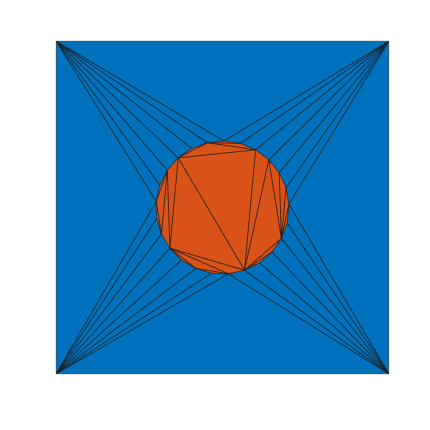

color = 1;
plotMeshes(vert,tria,tnum, color);

### Add mesh seeds to boundary

See demo16 for more examples. [https://mjx888.github.io/im2mesh_demo_html/demo16.html](https://mjx888.github.io/im2mesh_demo_html/demo16.html)

We use function xyRange to get the range of x y coordinates in boundary or polyshape.

[xmin, xmax, ymin, ymax] = xyRange( bounds );

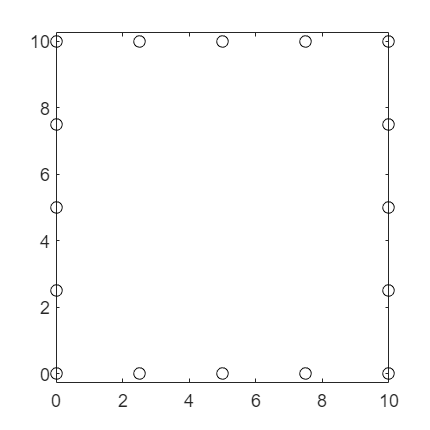

points = [xmin, ymin;
          xmin, ymax;
          xmax, ymax;
          xmax, ymin;
          xmin, ymin;
          ];

iters = 2;
points = insertMidPnt( points, iters );

plot( points(:,1), points(:,2), 'ko' ); 
axis equal

We use function addPnt2Bound to add point to boundary. 

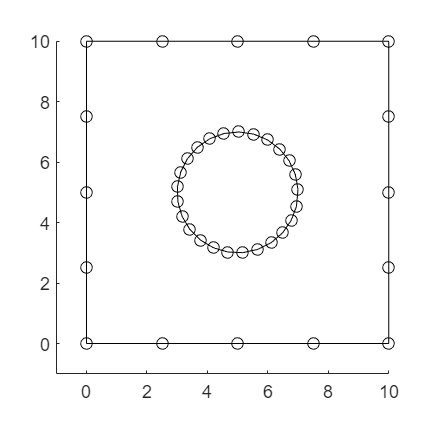

tol_dist = 1e-2;    % distance tolerance
newB = bounds;
newB = addPnt2Bound( points, newB, tol_dist );

% show all vertices
plotBounds( newB, false, 'ko-' );  

### Generate mesh via MESH2D

To generate mesh, we use function bounds2mesh.

Note that function bounds2mesh uses [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda) as mesh generator.

hmax = 500; 
grad_limit = 0.5;
opt = [];
opt.tf_preserve = 1;
opt.tf_smooth = 1;

[vert,tria,tnum,vert2,tria2] = bounds2mesh( newB, hmax, grad_limit, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          1                 41                 64
          6                 41                152


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          0                 41                 64
          8                 41                236


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------



Plot mesh.

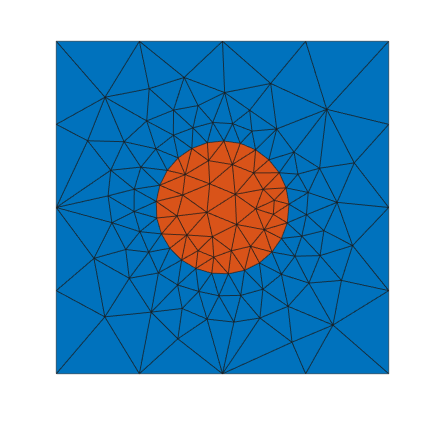

color = 1;
plotMeshes(vert,tria,tnum, color);

We can use function tricost to check the mesh quality. 

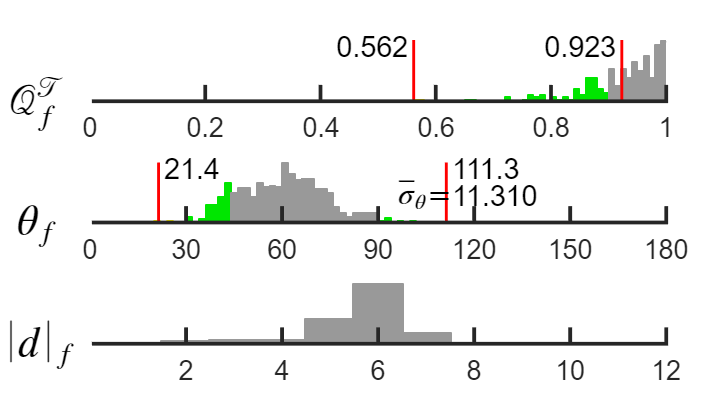

tricost( vert, tria );

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo